# Treasure Hunt Game

Welcome to this MATLAB Module designed to teach you how to make a fun treasure hunting game, while learning some core Computer Science concepts along the way. We recommend that you complete our other module: Fundementals of Programming to help better understand the concepts brought up in this module. Hope you enjoy!

The game will look like this when it is finished:

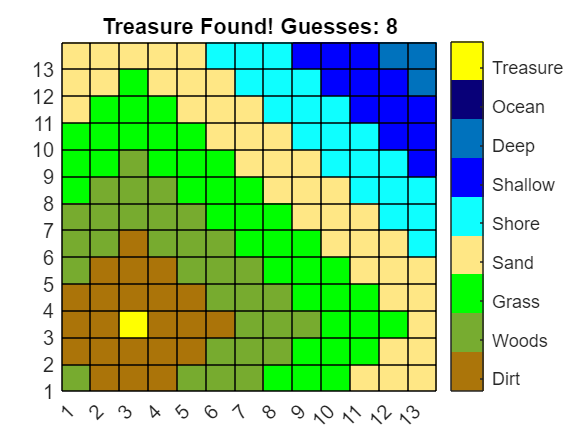

## Section 1: Creating Variables

Variables are a great way to store information to use for later. Some information for this game we want to save includes: the board size, the treasure location, and the numer of guesses made.

Let's start off with the board size. Start by naming your variables. I recommend: columns and rows or length and width. If you prefer, instead you can include only one variable if you want the board to always be a square.

Once your variables have a name, they must equal something. In this case we want them to be an integer that is between 6 and 20.

columns = 15
rows = 15 

If you want to allow the player to change the size of the board to make the game harder or easier, we can add a live control to make that easier for them. You can add a slider to change the value as you wish (Under Control in the Live editor Tab). To edit the slider configurations: Right Click -> Configure controls. Choose a min and max value for the sliders.

columns = 14

columns = 14

rows = 14

rows = 14

You can use old variables to make new ones. Try subtracting one from the columns.

limitC = columns - 1

limitC = 13

limitR = rows - 1

limitR = 13

A matlab built in function allows you to easily excute an operation. Functions can be used to generate new variables.

treasureX = randi([1 limitC])

treasureX = 9

treasureY = randi([1 limitR])

treasureY = 7

%Number of guesses the player made
guessNum = 0

## Working with Matricies

%Creates the blank map
map = zeros(rows, columns)

map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0


map(map == 0) = NaN

map =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN



%Creates the colored in Map
[x2,y2] = meshgrid(1:columns,1:rows)

x2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14


y2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9     9     9     9     9
    10    10    10    10    10    10    10    10    10    10    10    10    10    10


taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:))

taxiMatrix =     14
    13
    12
    11
    10
     9
     8
     9
    10
    11


finalMap = reshape(taxiMatrix,rows,columns)

finalMap =     14    13    12    11    10     9     8     7     6     7     8     9    10    11
    13    12    11    10     9     8     7     6     5     6     7     8     9    10
    12    11    10     9     8     7     6     5     4     5     6     7     8     9
    11    10     9     8     7     6     5     4     3     4     5     6     7     8
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
     8     7     6     5     4     3     2     1     0     1     2     3     4     5
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
    11    10     9     8     7     6     5     4     3     4     5     6     7     8



%Treasure is very high values to it shows up correctly
finalMap(treasureY,treasureX) = 500

finalMap =     14    13    12    11    10     9     8     7     6     7     8     9    10    11
    13    12    11    10     9     8     7     6     5     6     7     8     9    10
    12    11    10     9     8     7     6     5     4     5     6     7     8     9
    11    10     9     8     7     6     5     4     3     4     5     6     7     8
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
     8     7     6     5     4     3     2     1   500     1     2     3     4     5
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
    11    10     9     8     7     6     5     4     3     4     5     6     7     8



%The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0]

cmap =     0.6706    0.4588    0.0392
    0.4667    0.6745    0.1882
         0    1.0000         0
    1.0000    0.9059    0.5216
    0.0588    1.0000    1.0000
         0         0    1.0000
         0    0.4471    0.7412
    0.0314         0    0.4706
    1.0000    1.0000         0


guessNum = 0

## Creating Plots and Modifying Them

%Board Setup
p = pcolor(map)

p =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14]
           YData: [14×1 double]
           ZData: [14×14 double]
           CData: [14×14 double]

  Show all properties


hold on
xticks(1:1:limitC)
yticks(1:1:limitR)

colormap(cmap)
clim([0 rows*2])

c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


c.Ticks = 1:rows*2

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


c.TickLabels = [string(1:rows*2-3), '', 'Treasure', '', '']

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


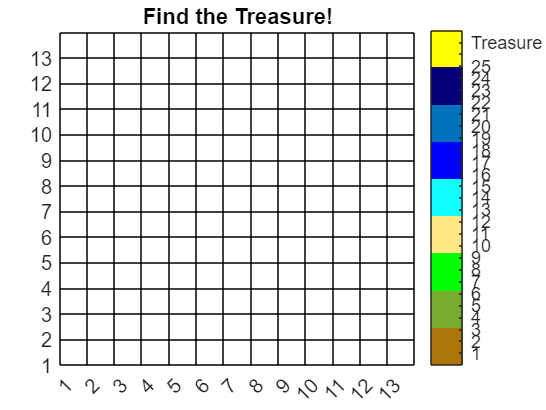


title("Find the Treasure!")

## If Statements and User Input

%Play Game
 

if(guessNum ~= 0)
    guessX = 5;
    guessY = 3;

    %Run function to check guesses
    playGame(treasureX,treasureY,map,finalMap,guessX,guessY,guessNum)
    guessNum = guessNum + 1;
else
    %Increments the Guess Numbers to start the game
    guessNum = guessNum + 1;
end


## Creating and Using Functions

function playGame(tX,tY,m,fm,gX,gY,gN)
    
    %If the guess is equal to the treasure location
    if(gX == tX)&&(gY == tY)
        %Fill in the whole grid
        pcolor(fm);
        %Display the new title
        finish = "Treasure Found! Guesses: " + gN;
        title(finish);
    %If the guess is not equal to the treasure
    else
        %Fill in the color of the location the guessed
        m(gY,gX) = fm(gY,gX);
        pcolor(m);
        
        %Display hint and guess number
        help = "You are " + string(fm(gY,gX)) + " away from the treasure.";
        guess = "Guess: " + gN;
        disp(help);
        disp(guess);
        disp("Guess again!");
        
    end
end